clear all
close all
clc

rng(1);

load('Benchmark_EEG_medium')
load('Benchmark_EEG_small')




Preprocessing Data

partici = 2 

partici = 2


[input,output] = cleanEEG(EEGdata,partici);



% average over periods and downsample, see Section II-B of paper
for Sidx=1:PAR
    smalldata.u(Sidx,:,:)=squeeze(mean(EEGdata{Sidx}.angle(:,:,1:ds:end),2)/0.12+0.5);
    smalldata.y(Sidx,:,:)=squeeze(mean(EEGdata{Sidx}.comp(:,:,1:ds:end),2))/8+0.5;
end

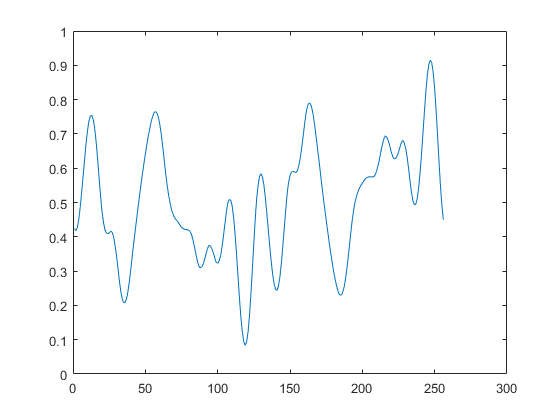


plot(squeeze(smalldata.u(1,1,:)))

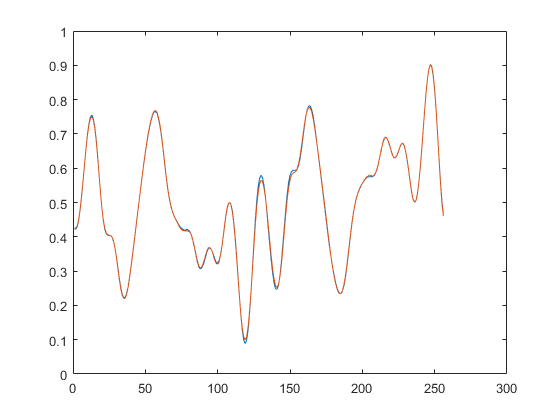

plot(EEGclean{1}.in{1}(:,1:2))

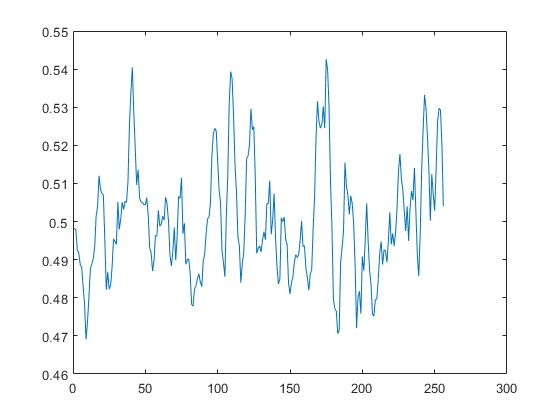


plot(squeeze(smalldata.y(1,1,:)))

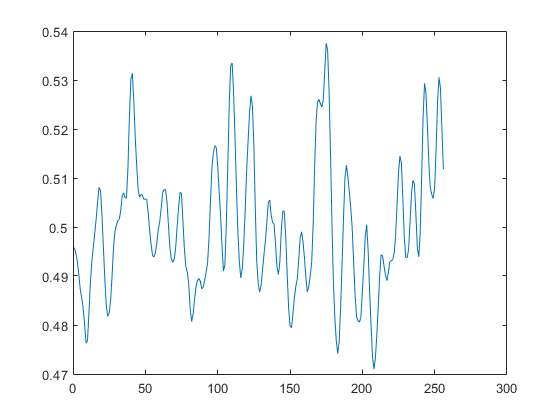

plot(mean(EEGclean{1}.out{1}(:,:)'))

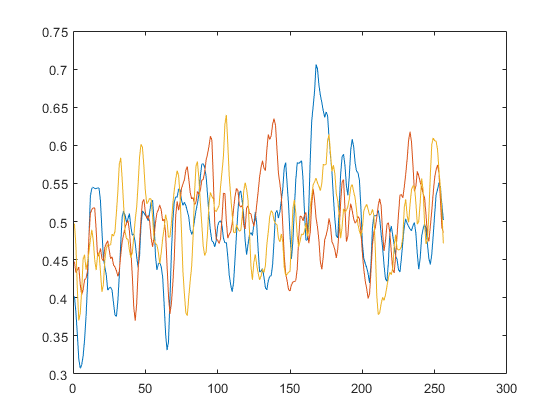

plot((EEGclean{1}.out{1}(:,1:3)))



var(squeeze(smalldata.y(1,1,:)))

ans = 2.2485e-04

var(mean(EEGclean{1}.out{1}(:,:)'))

ans = 1.9008e-04

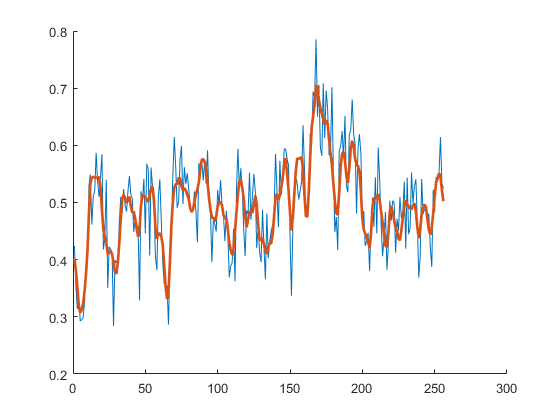


figure;
hold on
plot(squeeze((EEGdata{1}.comp(1,1,1:ds:end))/8+0.5))
plot((EEGclean{1}.out{1}(:,1)),'linewidth',2)
hold off


FY = mag2db(abs(fft((squeeze((EEGdata{1}.comp(1,2,1:1:end))))/8+0.5)));
FY2 = mag2db(abs(fft((squeeze((EEGdata{1}.comp(1,2,1:1:end))))/8+0.5)));
FYY = mag2db(abs(fft((squeeze((EEGdata{1}.comp(1,2,1:ds:end))))/8+0.5)));
FZ = mag2db(abs(fft(((EEGclean{1}.out{1}(:,2))))));
FZx = mag2db(abs(fft((mean(EEGclean{1}.out{1}')))));
FX = mag2db(abs(fft((squeeze(smalldata.y(1,1,:))))))

FX =    42.1465
  -13.7999
   -8.1543
  -35.6674
    2.9308
  -14.9364
  -10.1326
   -5.9869
   -8.4546
  -13.4704


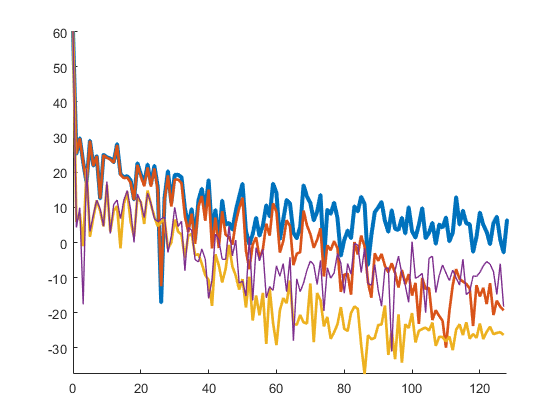


figure;
hold on
plot(0:1:1023,FY(1:floor(end/2)),'linewidth',3)
% plot(0:1:1023,FY2(1:floor(end/2)),'linewidth',2)
% plot(0:1:127,FYY(1:floor(end/2))+mag2db(8),'linewidth',1)
plot(0:1:127,FZ(1:floor(end/2))+mag2db(8),'linewidth',2)
plot(0:1:127,FZx(1:floor(end/2))+mag2db(8),'linewidth',2)
plot(0:1:127,FX(1:floor(end/2))+mag2db(8),'linewidth',1)
hold off
axis([0 128 -inf inf])


    
tinput = squeeze(smalldata.u(partici,:,:))';
toutput = squeeze(smalldata.y(partici,:,:))';

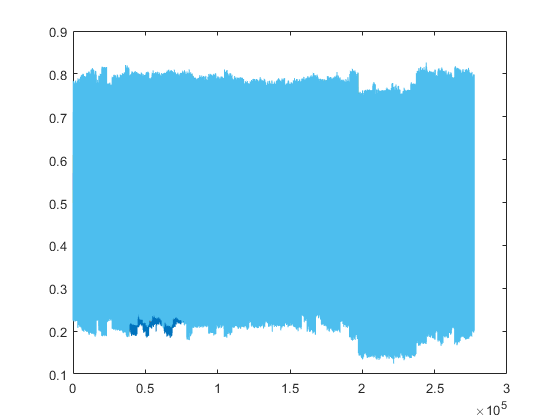

inlags=[6 5 4];
for l = 1:length(inlags)
u(:,l) = (reshape(input(end-inlags(l)-201:end-inlags(l)-1,:), [],1));
end

vlags=[10 9 8 6 5 4];
for l = 1:length(vlags)
v(:,l) = (reshape(input(end-vlags(l)-201:end-vlags(l)-1,:), [],1) - reshape(input(end-vlags(l)-200:end-vlags(l),:), [],1))/0.2+0.5;
end

plot(v)

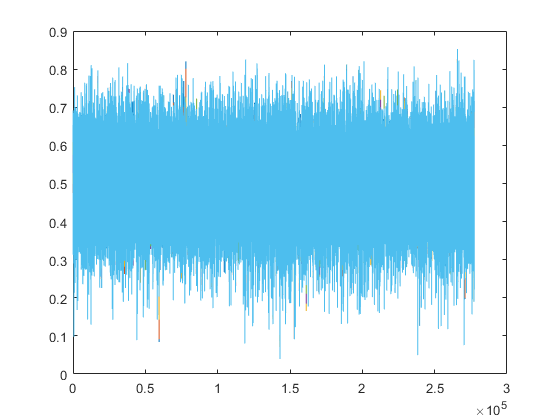

outlags=[0 1 2 3 4 5];
for l = 1:length(outlags)
y(:,l) = reshape(output(end-outlags(l)-200:end-outlags(l),:), [],1);
end

plot(y)


testind = [20000:20255 60000:60255 10000:10255 130000:130255 170000:170255 200000:200255 240000:240255];
trainind = setdiff([1:size(u,1)],testind);

featurez = [u(trainind,:) v(trainind,:) y(trainind,2:end)];
zeta = y(trainind,1);

tfeaturez = [u(testind,:) v(testind,:) y(testind,2:end)];
yt = y(testind,1);

% tfeaturez = featurez(1:400,:);
% yt = zeta(1:400,:);

Construct B-spline basis vectors


[N, d]=size(featurez); 

n = 2;                 %degree B-spline
m = 4;                  %Number of knot intervals
In = n+m;

un = basisvectors(featurez,n,m);



Initialize tensor train

% Choose TT-ranks
maxrank = 10;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank))

r =      1     6    10    10    10    10    10    10    10    10    10    10    10     6     1



[TN,Vm,Vp] = initTT(un,r,d);


Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %Degrees of freedom/ TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %ratio

Compression: 8.6672e-08


Optimize TT cores

lambda=10^-5

lambda = 1.0000e-05

difforder=2;
MAXITR = d;

nselect = floor(logspace(log10(dof*2/N),0,MAXITR)*0.5*N);

% MAXITR = 2;
% nselect = ones([1,MAXITR])*N

[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,nselect,lambda,difforder);

    "iteration:"    "2"    "2.8887"

    "iteration:"    "3"    "5.9177"

    "iteration:"    "4"    "9.2946"

    "iteration:"    "5"    "12.7163"

    "iteration:"    "6"    "16.4266"

    "iteration:"    "7"    "20.5871"

    "iteration:"    "8"    "25.1909"

    "iteration:"    "9"    "31.0291"

    "iteration:"    "10"    "36.428"

    "iteration:"    "11"    "42.9043"

    "iteration:"    "12"    "50.3488"

    "iteration:"    "13"    "59.6913"

    "iteration:"    "14"    "71.4705"



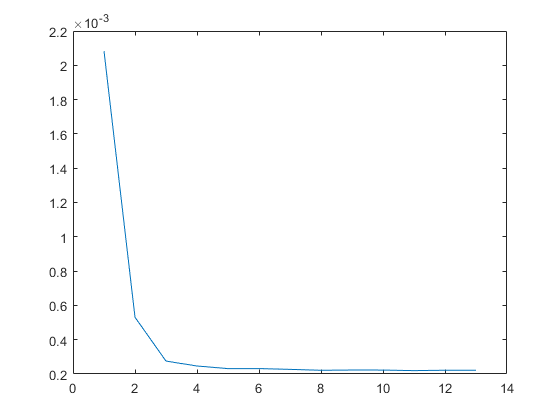


plot(res1)

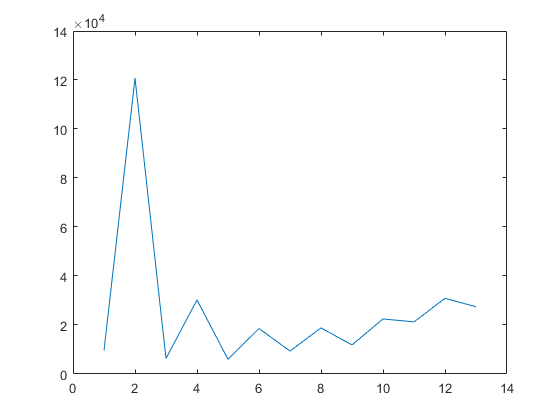

plot(res2)


res1(end)

ans = 2.2206e-04

Evaluate Test data

yhat = evalspline(TN,tfeaturez,n,m);


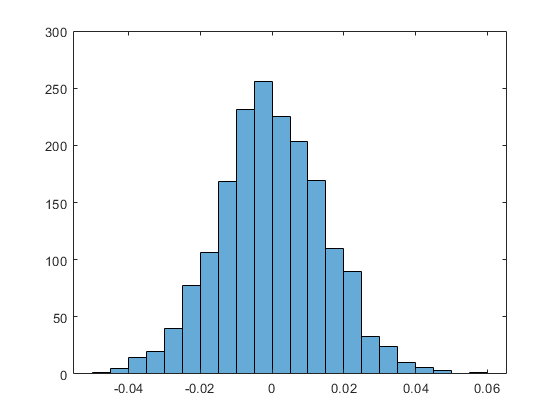

erboi = (yhat-yt);
histogram((erboi)');

VAF = 1-var(erboi)/var(yt)

VAF = 0.9657

MSE = immse(yhat,yt)

MSE = 2.2138e-04

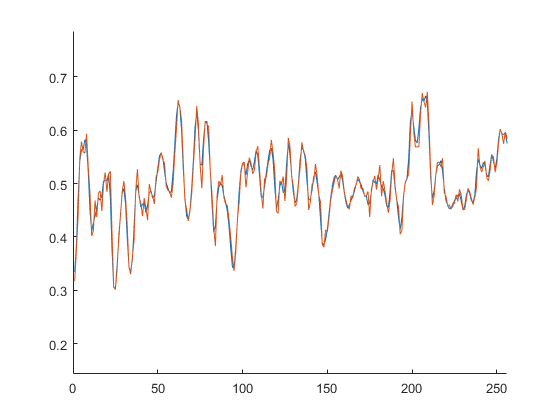


figure
hold on
plot(yt)
plot(yhat)
hold off
axis([0 256 -inf inf])

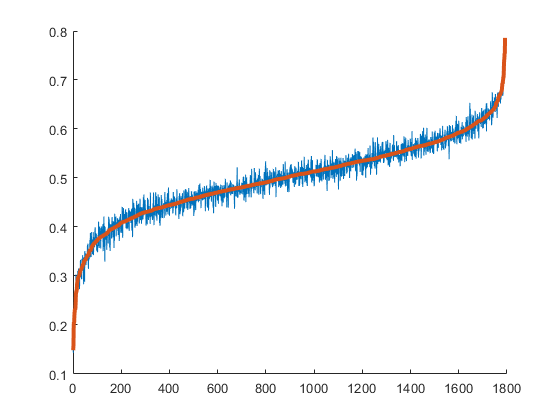


%  Visualize errors
[sortout,Iss]=sort(yhat);
figure
hold on
plot(yt(Iss))
plot(sortout,'Linewidth',3)
hold off

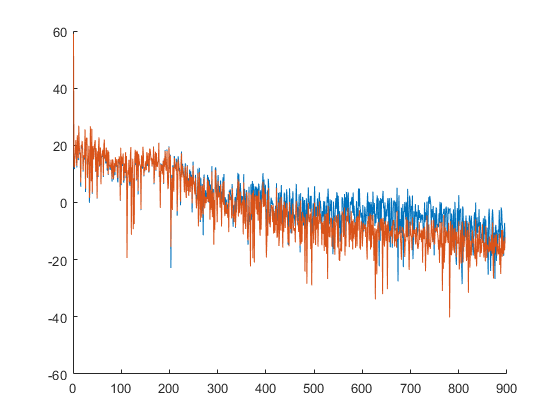


FY = mag2db(abs(fft(yhat)));
FZ = mag2db(abs(fft(yt)));

figure;
hold on
plot(FY(1:floor(end/2)))
plot(FZ(1:floor(end/2)))
hold off